# Fatigue

## Accès dossier et choix essai

clear;
Type = "C6C0SN";
Materiau = "3135";
Eprouvette ='1';
Numero = '2';
 
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

## Ajout de descripteurs

% Calcul du RA et ajout dans HDD (rise angle, Cf. Aggelis 2011)
RA(1) = HDD.RISE(1)/HDD.AMP(1);
CumuRA(1) = RA(1);
for i = 2:height(HDD)
    RA(i) = HDD.RISE(i)/HDD.AMP(i);
    CumuRA(i) = CumuRA(i-1)+RA(i);
end
RA = RA';
CumuRA = CumuRA';
HDD = addvars(HDD,RA,CumuRA);

## Tracé de graphique type

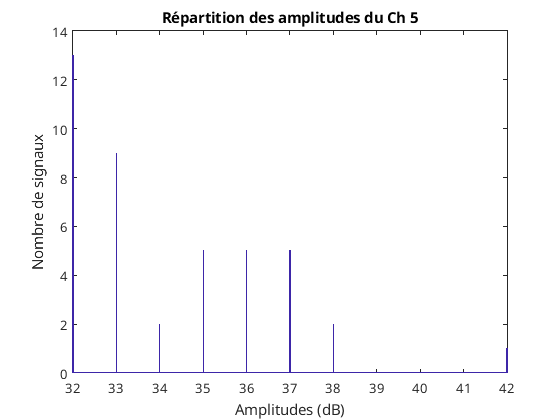

 
Ch =5;
x = find(HDD.CH==Ch);
% Pour multiplets : histogramme amplitude
figure();
hist(HDD.AMP(x),height(HDD));
title(strcat("Répartition des amplitudes du Ch ",string(Ch)));
xlabel("Amplitudes (dB)");
ylabel("Nombre de signaux");

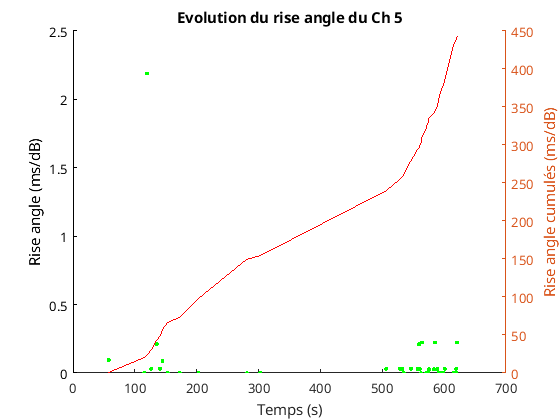


% RA 
figure();
hold on
x = find(HDD.CH==Ch);
plot(HDD.Time(x),HDD.RA(x),'g.');
ylabel("Rise angle (ms/dB)");
xlabel("Temps (s)");
yyaxis right;
plot(HDD.Time(x),HDD.CumuRA(x),'r-');
ylabel("Rise angle cumulés (ms/dB)");
title(strcat("Evolution du rise angle du Ch ",string(Ch)));

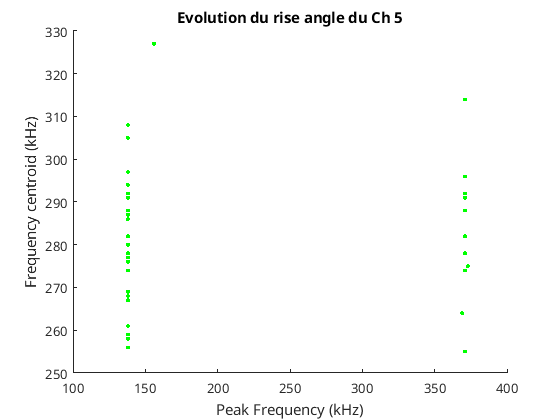


% Freq 
figure();
hold on
plot(HDD.P_FRQ(x),HDD.FRQ_C(x),'g.');
ylabel("Frequency centroid (kHz)");
xlabel("Peak Frequency (kHz)");
title(strcat("Evolution du rise angle du Ch ",string(Ch)));